%let each unit be 1cm
%trying to achieve forward kinematics: 
% the position of the tool tip in terms of the base reference frame 
% (gives the actual position) then can determine the desired tool tip 
% position (relative to the heart)

% HRF = heart reference frame
% VRF = fixed point where the voice coil actuator sits inside the device (non-actuating part)
% TRF = tool-tip reference frame (actuating)
% BRF = base of device

unit vectors for reference frame 1

% Define the plane
[X, Y] = meshgrid(0:40.2, 0:80.4);%should be 40.2 & 80.4
Z = zeros(size(X));% Z is constant for a flat plane

% Plot the plane
surf(X, Y, Z, 'FaceAlpha', 0.5);
hold on;

%BRF_pt = [40.2-13.5, 21.0, 0];%40.2-13.5 x offset
BRF_pt = [30, 20, 0]

BRF_pt =     30    20     0


DH PARAMETERS--> Calculate transformation matrices

l01A=26.1;d01=0;l01B=0;l45A=10.7;1;l45B=11.5;l56A=2;d56potentiometer=2;l56B=5;
%l01A=10.1;d01=0;l01B=0;l45A=2.7;1;l45B=2.5;l56A=1;d56potentiometer=1;l56B=1;
%gyro
theta2_yaw=(0)*pi/180;
theta3_pitch=(0)*pi/180;
theta4_roll=(0)*pi/180;
%           a       α       d                           θ
dhparams = [0   	0	    l01A+d01+l01B               0
            0	    pi/2    0                           theta2_yaw+pi/2%so starting oritentation is towards +y
            0	    pi/2    0                           theta3_pitch+pi/2%so starting orientation is L shape
            0	    0       0                           theta4_roll
            l45A    0       0                           0
            0       0       l45B                        0
            0	    0	    l56A+d56potentiometer+l56B  0];

%%%%% practice params %%%%%%
% dhparams = [10 0 0  pi/2;
%             10 0 0 -pi/2;
%             10 0 0 -pi/2;];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%hold the joint matrices
individualJT= cell(1,3);

%cycle through joints & plot them
n = size(dhparams, 1);

T01= JointTransformation(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4));
T12= JointTransformation(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4));
T23= JointTransformation(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4));
T34= JointTransformation(dhparams(4,1), dhparams(4,2), dhparams(4,3), dhparams(4,4));
T45= JointTransformation(dhparams(5,1), dhparams(5,2), dhparams(5,3), dhparams(5,4));
T56= JointTransformation(dhparams(6,1), dhparams(6,2), dhparams(6,3), dhparams(6,4));
T67= JointTransformation(dhparams(7,1), dhparams(7,2), dhparams(7,3), dhparams(7,4));


%T02=T01*T12; %gyro p1
%T03=T01*T12*T23; %gyro p2
T04=T01*T12*T23*T34;%gyro p3
T05=T01*T12*T23*T34*T45;
T06=T01*T12*T23*T34*T45*T56;%tool tip to base T06
T07=T01*T12*T23*T34*T45*T56*T67%tool tip to base T06

T07 =    -0.0000    1.0000    0.0000    0.0000
    0.0000   -0.0000    1.0000   20.5000
    1.0000    0.0000   -0.0000   36.8000
         0         0         0    1.0000


Transform tooltip in terms of POI

POI_pt=[20,60,10];

%define transformatiob matrix between BRF and POI
TBRFPOI=[1 0 0 POI_pt(1)-BRF_pt(1);
 0 1 0 POI_pt(2)-BRF_pt(2);
 0 0 1 POI_pt(3)-BRF_pt(3);
 0 0 0 1];
tooltipwrtPOI_pt=TBRFPOI*[T07(1,4);T07(2,4);T07(3,4);1]

tooltipwrtPOI_pt =   -10.0000
   60.5000
   46.8000
    1.0000


tooltipwrtBRF_pt=[T07(1,4);T07(2,4);T07(3,4);1]

tooltipwrtBRF_pt =     0.0000
   20.5000
   36.8000
    1.0000



% if the euclidean distance between the tooltip and POI is < 10,
%change the length of the 

PLOT points for robot

% Define the POI point on the plane

% Create unit vectors
u = [1, 0, 0]; % Unit vector in x-direction
v = [0, 1, 0]; % Unit vector in y-direction
w = [0, 0, 1]; % Unit vector in z-direction
% Plot the unit vectors
plotunitvector(BRF_pt,u,v,w)
plotunitvector([0,0,0],5*u,5*v,5*w)
plotunitvector(POI_pt,u,v,w)


%tool tip reference frame (position of BRF + distance from BRF to tool tip)
tooltip_pt = [BRF_pt(1)+T07(1,4),BRF_pt(2)+T07(2,4),BRF_pt(3)+T07(3,4)];
%unit vectors are the column of the rotational matrix
u_tooltip=T07(1:3,1);%1:3 selects first 3 rows
v_tooltip=T07(1:3,2);
w_tooltip=T07(1:3,3);
% Plot the unit vectors
plotunitvector(tooltip_pt,u_tooltip,v_tooltip,w_tooltip)

%T04 gyro
T04_pt = [BRF_pt(1)+T04(1,4),BRF_pt(2)+T04(2,4),BRF_pt(3)+T04(3,4)];
%unit vectors are the column of the rotational matrix
u_T04=T04(1:3,1);%1:3 selects first 3 rows
v_T04=T04(1:3,2);
w_T04=T04(1:3,3);
% Plot the unit vectors
plotunitvector(T04_pt,u_T04,v_T04,w_T04)


T05_pt = [BRF_pt(1)+T05(1,4),BRF_pt(2)+T05(2,4),BRF_pt(3)+T05(3,4)];
%unit vectors are the column of the rotational matrix
u_T05=T05(1:3,1);%1:3 selects first 3 rows
v_T05=T05(1:3,2);
w_T05=T05(1:3,3);
% Plot the unit vectors
plotunitvector(T05_pt,u_T05,v_T05,w_T05)

%T06 gun actuator start
T06_pt = [BRF_pt(1)+T06(1,4),BRF_pt(2)+T06(2,4),BRF_pt(3)+T06(3,4)];
%unit vectors are the column of the rotational matrix
u_T06=T06(1:3,1);%1:3 selects first 3 rows
v_T06=T06(1:3,2);
w_T06=T06(1:3,3);
% Plot the unit vectors
plotunitvector(T06_pt,u_T06,v_T06,w_T06)

%plot lines
plot_parametricline(BRF_pt,T04_pt)
lBRF_4= distance3D(BRF_pt,T04_pt)

lBRF_4 = 26.1000

plot_parametricline(T04_pt,T05_pt)
l4_5=distance3D(T04_pt,T05_pt)

l4_5 = 10.7000

plot_parametricline(T05_pt,T06_pt)
l5_6= distance3D(T05_pt,T06_pt)

l5_6 = 11.5000

plot_parametricline(T06_pt, tooltip_pt)
l6_7= distance3D(T06_pt, tooltip_pt)

l6_7 = 9

display

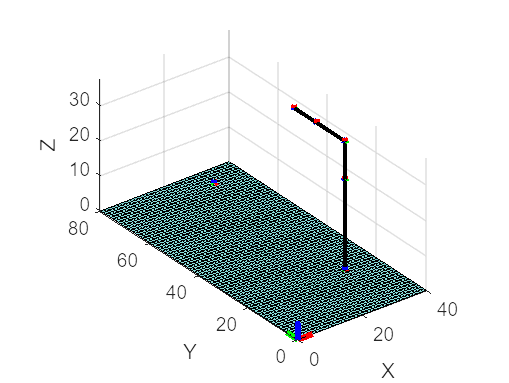

% Set axis properties
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

functions 

function T = JointTransformation(a, alpha, d, theta)
    T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
         sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
         0          sin(alpha)            cos(alpha)             d
         0          0                     0                      1];
end
% JointTransformation(dhparams(i,1), dhparams(i,2), dhparams(i,3), dhparams(i,4));

%plot unit vectors
function P = plotunitvector(pt,u,v,w)
    quiver3(pt(1), pt(2), pt(3), u(1), u(2), u(3), 'r', 'LineWidth', 3);
    quiver3(pt(1), pt(2), pt(3), v(1), v(2), v(3), 'g', 'LineWidth', 3);
    quiver3(pt(1), pt(2), pt(3), w(1), w(2), w(3), 'b', 'LineWidth', 3);
end

%plot parametric lines between 2 points
function plot_parametricline(p1, p2)
    t = [0 1]; % Parameter range
    x = p1(1) + t*(p2(1) - p1(1)); % Parametric equation for x
    y = p1(2) + t*(p2(2) - p1(2)); % Parametric equation for y
    z = p1(3) + t*(p2(3) - p1(3)); % Parametric equation for z
    plot3(x, y, z,'k','LineWidth', 2);
end

%euclidean distance
function d = distance3D(p1, p2)
    d = sqrt(sum((p2 - p1).^2));
end
